# This script is intended to show some basic functions of Matlab useful for engineering practices. 

## Creating a matrix and a vector to work with

4 by 4 matrix with random integers between 10 and 100:

randomMatrix = randi([10 100], 4, 4);

Row vector with 7 elements from 1 to 7 increasing by 1:

seriesVector = 1:7;

## Sum and product of vector elements

### Sum of vector elements

sumOfVector = sum(seriesVector);

### Product of vector elements

prodOfVector = prod(seriesVector);
factorial7 = prod(seriesVector);

## Sum and product of matrix elements

### Summing matrix elements along the rows (1st dimension)

Summing matrix elements along the rows means that the sum of each column vector constructing the matrix is computed as:

sumOfEachMatrixColumn = sum(randomMatrix, 1);
sumOfEachMatrixColumnOtherForm = sum(randomMatrix);

### Summing matrix elements along the columns (2nd dimension)

Summing matrix elements along the columns means that the sum of each row vector constructing the matrix is computed as:

sumOfEachMatrixRow = sum(randomMatrix, 2);

### Sum of all matrix elements

sumOfMatrixElements = sum(randomMatrix, 'all');
sumOfMatrixElementsOtherForm = sum(randomMatrix(:));
sumOfMatrixElementsOtherForm2 = sum(sum(randomMatrix)); % not suggested to use

### Product of each matrix column

prodOfEachMatrixColumn = prod(randomMatrix, 1);
prodOfEachMatrixRow = prod(randomMatrix, 2);
productOfEachElements = prod(randomMatrix, 'all');

## Euclidean norm: the Euclidean length of a vector

vectorVariable = [1 2 3];
lengthOfVector = norm(vectorVariable);

## Read Covid database to work with

[dates, numberOfCases] = readCovidDataBase({'Hungary'});
countries = {'Germany', 'France', 'Austria', 'Hungary', 'Romania'};

The variable $\texttt{months}$ contains the months (with numbers) included in the database. The number of cases in a specific country within a month is stored into $\texttt{covidDataMatrix}$, whose rows and columns correspond to the months and countries, respectively.

[months, covidDataMatrix] = createCovidDataMatrix(countries);

## Min / max

### Min value and min index of a vector

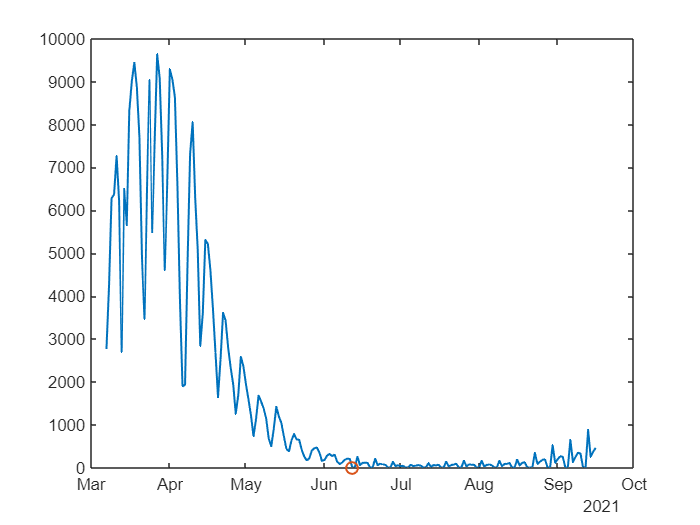

[minValue, minIndex] = min(numberOfCases);

minDate = dates(minIndex);

figureObject2 = figure;
axisObject2 = axes(figureObject2);
plot(axisObject2, dates, numberOfCases, 'LineWidth', 1.2);
hold(axisObject2, 'on')
plot(axisObject2, minDate, minValue, 'Marker', 'o', 'MarkerSize', 7, ...
    'LineWidth', 1.2)
hold(axisObject2, 'off')

### Min/max value and min/max index of matrix

Min/max values of a matrix along a specific dimension

Max of each columns (countries):

[maxValueOfCols, maxIndexOfCols] = max(covidDataMatrix);

Max of each rows (month):

[minValueOfRows, minIndexOfRows] = min(covidDataMatrix, [], 2); % max of each rows

Visualize values with 3D bars

numOfColumns = size(covidDataMatrix, 2);
columnIndices = 1 : numOfColumns;
maxColor = 'red';
numOfRows = size(covidDataMatrix, 1);
rowIndices = 1 : numOfRows;
minColor = 'green';
markerSize = 20;

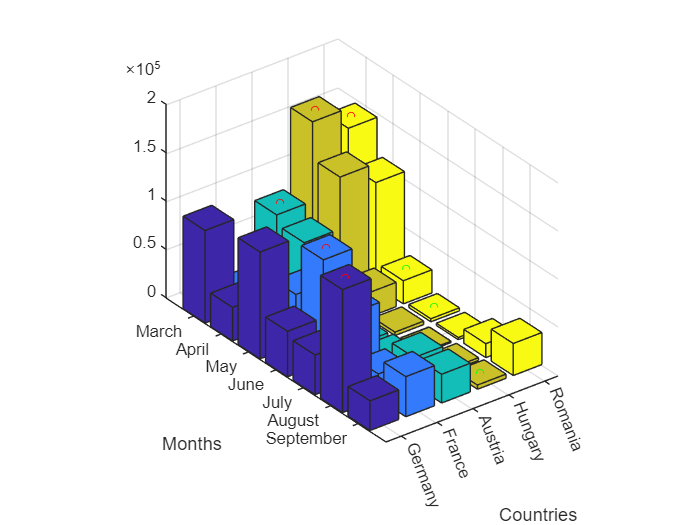

figure
% Create bar3 of covidDataMatrix
bar3(covidDataMatrix);

hold on
% Create scatter3 of columnIndices, maxIndexOfCols, and maxValueOfCols
scatter3(columnIndices,maxIndexOfCols,maxValueOfCols,markerSize,maxColor,'DisplayName','maxValueOfCols');
% Create scatter3 of minIndexOfRows, rowIndices, and minValueOfRows
scatter3(minIndexOfRows,rowIndices,minValueOfRows,markerSize,minColor,'DisplayName','minValueOfRows');
hold off
xlabel('Countries')
xticklabels(countries)

ylabel('Months')
yticklabels(months)

Max value of the complete matrix (index cannot be given directly)

maxValue = max(covidDataMatrix,[], 'all');

### Arithmetics

#### Mean value ~ average 

meanValue = mean(numberOfCases);

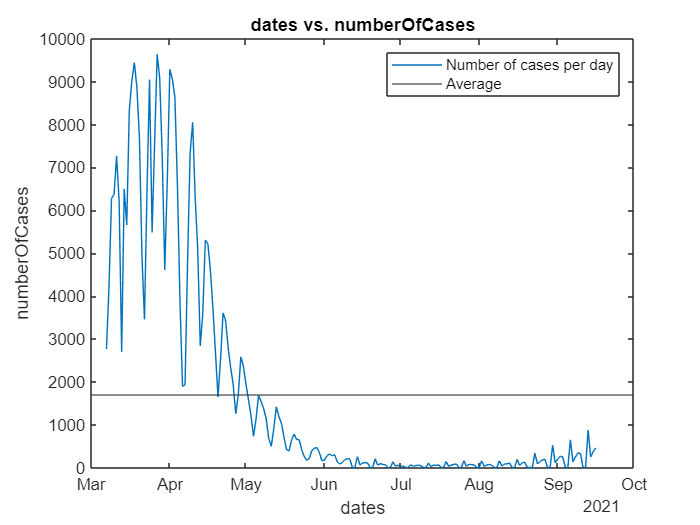

% Create plot of dates and numberOfCases
h2 = plot(dates,numberOfCases,'DisplayName','numberOfCases');

% Add xlabel, ylabel, title, and legend
xlabel('dates')
ylabel('numberOfCases')
title('dates vs. numberOfCases')
legend
hold on
yline(meanValue)
hold off
legend('Number of cases per day', 'Average')

#### Cumulative sum

cumulativeSum = cumsum(numberOfCases);

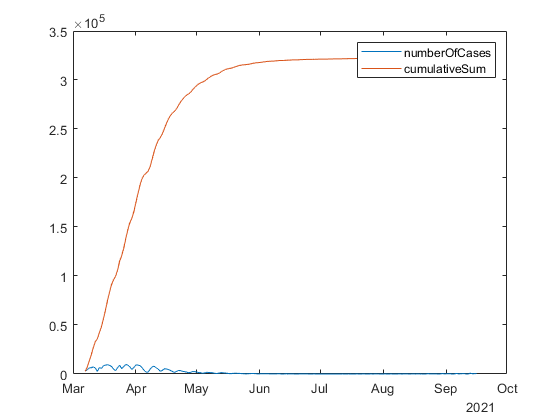

figure
% Create plot of dates and numberOfCases
plot(dates,numberOfCases,'DisplayName','numberOfCases');

hold on
% Create plot of dates and cumulativeSum
plot(dates,cumulativeSum,'DisplayName','cumulativeSum');
hold off

legend

## Differences ~ numerical derivative

timeVect = 0:0.1:10;
positionVect = cos(timeVect);
numerDerivative = diff(positionVect) ./ diff(timeVect);

Append 0 (starting velocity) to derivative vector to avoid dimension mismatch

numerDerivative = [0, numerDerivative];

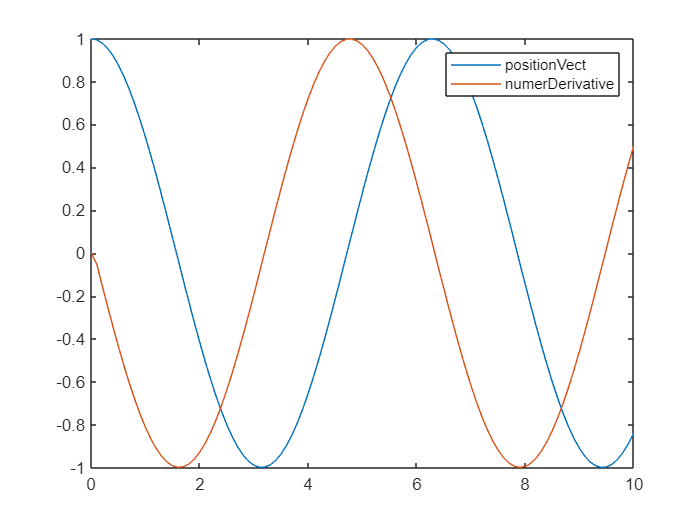

figure
% Create plot of timeVect and positionVect
plot(timeVect,positionVect,'DisplayName','positionVect');

hold on
% Create plot of timeVect and numerDerivative
plot(timeVect,numerDerivative,'DisplayName','numerDerivative');
hold off

legend

## Noise filtering with moving mean

Simulating noisy measurements of the position by adding some random noise to real poistion:

noisyMeasurement = positionVect + rand(size(timeVect));

#### Symmetric moving average

The symmetric moving average is able to efficiently obtain the actual value of a noisy measurement by considering the past and future trends of the signal with the same weight. The filtered value is computed by the average of the samples in the moving window, which contains as many samples from the past as it does from the future if the window size is odd. If the window size is even, it includes one more sample from the past. The symmetric moving average is the best concept to remove the noise from the raw measurements during offline evaluation since it does not cause significant phase delay.

In the following example the filtering utilizes 20 samples in total to filter the noisy measurement.

filteredMeasurementSymmetric = movmean(noisyMeasurement, 20);

#### Moving average with backward-looking window

Backward-looking window means that the filtering uses only past data to estimate the actual value of the noisy measurement. This concept can be used online when the filtering is performed in a real-time environment. However, it can cause a severe delay in the estimation (see the example below). 

In the following example, besides the current measurement, the filtered value encapsulates 20 samples preceding the current value. 

filteredMeasurementBackward = movmean(noisyMeasurement, [20 0]);

#### Moving average with forward-looking window

In forward-looking filtering, only future data is used to estimate the actual value of the filtered signal. This concept cannot be used online since future samples are not available in a real-time environment. Contrary to the backward-looking filter, the forward-looking does not delay the data but speeds it up. Therefore, the forward-looking filter is not frequently used.  

filteredMeasurementForward = movmean(noisyMeasurement, [0 20]);

#### Moving average with backward + forward looking window

It can also be exactly specified how many past and future samples are used to filter the noisy measurement. The more measurements are used from the past; the more delayed the estimation will be. While the more weight is put on the future, the more it will speed up the changes in the data. 

filteredMeasurementBackwardForward1 = movmean(noisyMeasurement, [15 4]);
filteredMeasurementBackwardForward2 = movmean(noisyMeasurement, [4 15]);

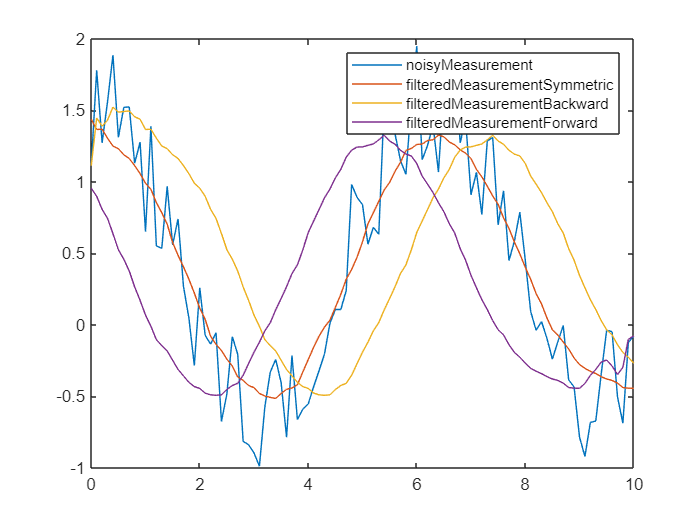

figure
% Create plot of timeVect and noisyMeasurement
plot(timeVect,noisyMeasurement,'DisplayName','noisyMeasurement');

hold on
% Create plot of timeVect and filteredMeasurementSymmetric
plot(timeVect,filteredMeasurementSymmetric,'DisplayName','filteredMeasurementSymmetric');
% Create plot of timeVect and filteredMeasurementBackward
plot(timeVect,filteredMeasurementBackward,'DisplayName','filteredMeasurementBackward');
% Create plot of timeVect and filteredMeasurementForward
plot(timeVect,filteredMeasurementForward,'DisplayName','filteredMeasurementForward');
hold off

legend